CL = sqrt((lambda+2*mu)/density);
CT = sqrt(mu/density);

kd1 = kd(n); % 第k阶波数
k = kd1/h;
w = wd*CT/h;

p = sqrt((w/CL)^2-k.^2);
q = sqrt((w/CT)^2-k.^2);

for ii = 1:50
	dx = 2*pi/k;
	x = ii*dx/50;

	y = Coordinate(bnd,2);
	% y = y(1);


	E = [exp(1i*p*y) exp(-1i*p*y) exp(1i*q*y) exp(-1i*q*y)];
	A = Amp(:,n); % 第n阶模态的幅值系数

	u =  E * diag([k, k, -q, q].*1i) * A .* exp(1i*k*x);
	v =  E * diag([p, -p k k].*1i) * A .* exp(1i*k*x);
	u = imag(u); v = real(v);
	% u = u./max(abs(u)); v = v./max(abs(v));

	t11 = E * diag([mu*(2*p^2-q^2-k^2)*[1 1], 2*mu*q*k*[1 -1]]) * A .* exp(1i*k*x);
	t12 = E * diag([2*mu*k*p*[-1 1], mu*(q^2-k^2)*[1 1]]) * A .* exp(1i*k*x);
	t22 = E * diag([-mu*(q^2-k^2)*[1 1], 2*mu*k*q*[-1 1]]) * A .* exp(1i*k*x);
	t11 = real(t11); t12 = imag(t12); t22 = real(t22);
	tx = t11+t12;
	ty = t12+t22;

## 合并x和y的位移/力

	tmpU = [u,v]';
	U = tmpU(:);

	tmpT = [tx,ty]';
	T = tmpT(:);

## 绘图检验

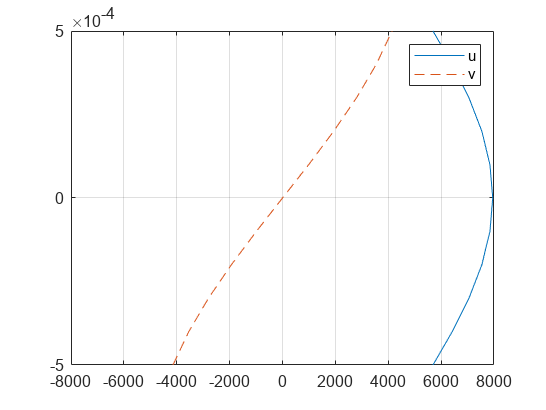

	[y1,I] = sort(y);
	plot(u(I),y1)

	grid on
	hold on
	plot(v(I),y1,'--')
	legend('u','v')
	hold off
	xlim([-8000 8000])
	pause(0.2)
end